# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `lgraph` 中创建层。

要了解详细信息，请参阅 [从深度网络设计器生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2024-03-16 00:43:37 自动生成

## 创建层图

创建层图变量以包含网络层。

lgraph = layerGraph();

## 添加层分支

将网络分支添加到层图中。每个分支均为一个线性层组。

tempLayers = imageInputLayer([6 1 1],"Name","imageinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([2 1],8,"Name","conv","Padding","same")
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu")
    convolution2dLayer([2 1],8,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([2 1],8,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([2 1],8,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([2 1],16,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_3")
    convolution2dLayer([2 1],16,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_4")
    convolution2dLayer([2 1],16,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([2 1],16,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([2 1],16,"Name","conv_8","Padding","same")
    batchNormalizationLayer("Name","batchnorm_8")
    reluLayer("Name","relu_6")
    convolution2dLayer([2 1],16,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")
    reluLayer("Name","relu_7")
    convolution2dLayer([2 1],16,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    reluLayer("Name","relu_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([2 1],16,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_9")
    convolution2dLayer([2 1],16,"Name","conv_12","Padding","same")
    batchNormalizationLayer("Name","batchnorm_12")
    reluLayer("Name","relu_10")
    convolution2dLayer([2 1],16,"Name","conv_13","Padding","same")
    batchNormalizationLayer("Name","batchnorm_13")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_3")
    reluLayer("Name","relu_11")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助变量
clear tempLayers;

## 连接层分支

连接网络的所有分支以创建网络图。

lgraph = connectLayers(lgraph,"imageinput","conv");
lgraph = connectLayers(lgraph,"imageinput","conv_2");
lgraph = connectLayers(lgraph,"batchnorm_3","addition/in2");
lgraph = connectLayers(lgraph,"batchnorm_2","addition/in1");
lgraph = connectLayers(lgraph,"relu_2","conv_4");
lgraph = connectLayers(lgraph,"relu_2","conv_7");
lgraph = connectLayers(lgraph,"batchnorm_6","addition_1/in1");
lgraph = connectLayers(lgraph,"batchnorm_7","addition_1/in2");
lgraph = connectLayers(lgraph,"relu_5","conv_8");
lgraph = connectLayers(lgraph,"relu_5","addition_2/in2");
lgraph = connectLayers(lgraph,"batchnorm_10","addition_2/in1");
lgraph = connectLayers(lgraph,"relu_8","conv_11");
lgraph = connectLayers(lgraph,"relu_8","addition_3/in2");
lgraph = connectLayers(lgraph,"batchnorm_13","addition_3/in1");

## 绘制层

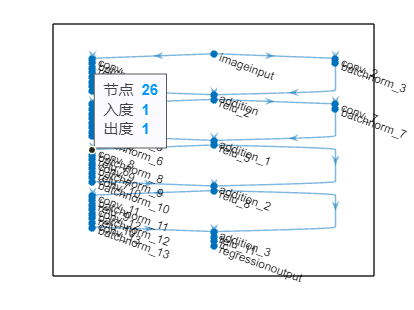

plot(lgraph);